# Projeto 1 da Disciplina 

Nome: Luis Paulo Siqueira Silva

RA: 183045

## Parte 0 - Dados de entrada

Para gerar os dados que serão usados em todo o trabalho, foram desenvolvidas alguma funções que se encontram no final do trabalho. Essas funções são responsáveis por pegar os digitos do RA e transforma-los em valores que atribuidos a algumas incógnitas das equações apresentadas.

RA = '183045';
d = converteRA(RA)

d =     1.0000
    8.0000
    3.0000
         0
    4.0000
    5.0000


[L, Izz, M0] = dados(d)

L = 45.0000

Izz = 0.0182

M0 = 1.8000e+04


E = 210e9;
densidade = 7850;

## Parte 1 - Tensões e deflexões em vigas

### Momento fletor

Usando a equação dada de Mz(x), variando o x em um intervalo de 0 < x < L, podemos chegar a um gráfico. Podemos observar que independente da forma que chegamos nesse gráfico, seja usando a função de singularidade ou pela definição de equações por partes, chegamos no mesmo resultado.

Além disos, podemos observar que o ponto em x no qual o módlo do momento fletor é máximo, é em x = L/2, como pode ser visto no gráfico.

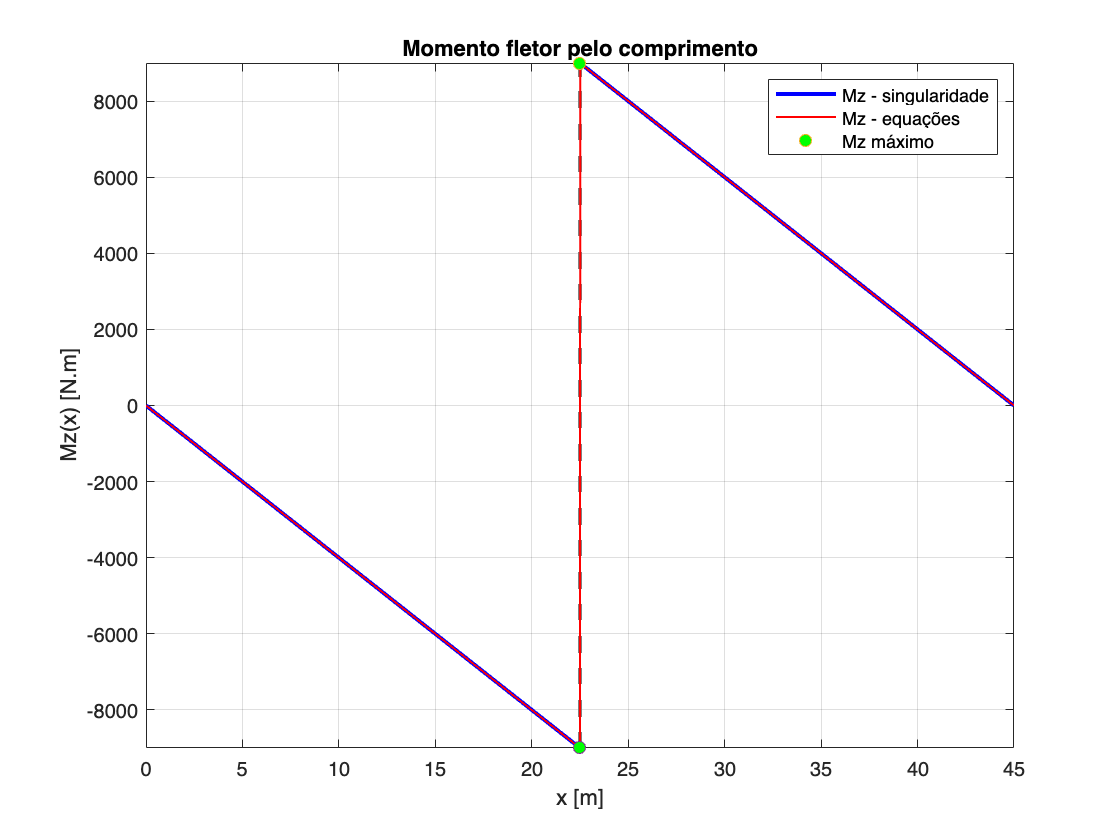

%% PARTE 1
P = M0/L;

%% momento fletor
%metodo 1 - usando singularidade
Mz = @(x) P*L - M0 - P*x + M0 * sing(x,L/2,0);

%metodo 2 - usando equacoes a partir do valor de x
x = [0:0.01:L];
for a = 1:length(x)
    if x(a) < L/2
        Mz2(a) = P*(L-x(a)) - M0;
    else
        Mz2(a) = P*(L-x(a));
    end
end

%fazendo o grafico
%pode-se observar que a mistura dos dois gráficos, um azul e o outro
%vermelho, geraram um gráfico roxo
figure
fplot(Mz, [0 L], 'b','LineWidth',2);
hold on;
title('Momento fletor pelo comprimento')
ylabel('Mz(x) [N.m]');
xlabel('x [m]');
plot(x, Mz2,'r','LineWidth',1);
grid on;
plot(L/2, Mz(L/2),'o','MarkerFaceColor','g');
plot(L/2, -Mz(L/2),'o','MarkerFaceColor','g');
legend('Mz - singularidade', 'Mz - equações','Mz máximo')
hold off;

Para melhor visualização dos gráficos, aqui estão eles separados, onde também pode-se observar a igualdade entre os dois.

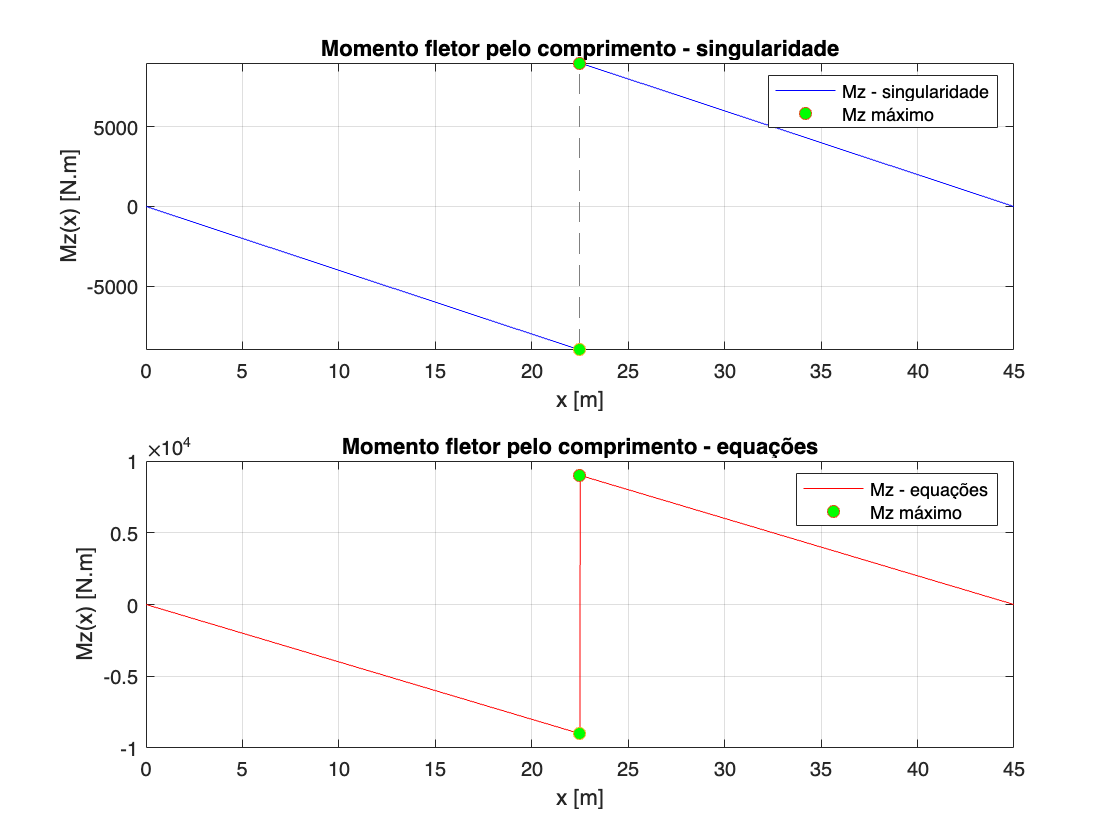

%para melhor visualizacao dos graficos
figure
subplot(2,1,1);fplot(Mz, [0 L], 'b')
hold on;
ylabel('Mz(x) [N.m]');
xlabel('x [m]');
title('Momento fletor pelo comprimento - singularidade')
grid on;
plot(L/2, Mz(L/2),'o','MarkerFaceColor','g')
plot(L/2, -Mz(L/2),'o','MarkerFaceColor','g')
legend('Mz - singularidade', 'Mz máximo')
hold off;

subplot(2,1,2);plot(x, Mz2,'r');
hold on;
ylabel('Mz(x) [N.m]');
xlabel('x [m]');
title('Momento fletor pelo comprimento - equações')
grid on;
plot(L/2, Mz(L/2),'o','MarkerFaceColor','g')
plot(L/2, -Mz(L/2),'o','MarkerFaceColor','g')
legend('Mz - equações', 'Mz máximo')
hold off;

### Deflexão

Usando a fórmula, variando o valor de x no intervalo de 0 < x < L, para diferentes valores de P, apresentados na legenda, chegamos ao seguinte gráfico:

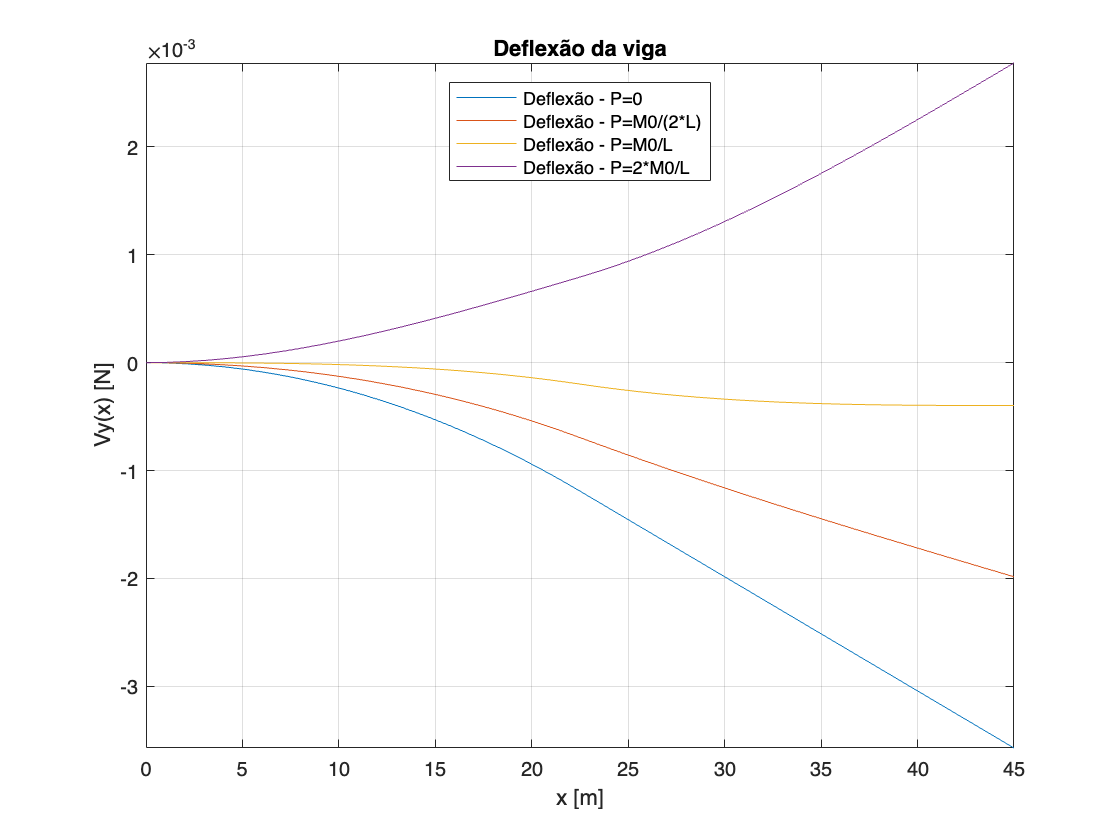

figure
%Deflexão
Vy = @(x) ((P*L-M0).*x.^2/2 - P/6.*x.^3 + M0/2*sing(x,L/2,2))/(E*Izz);

P1 = 0;
Vy1 = @(x) ((P1*L-M0).*x.^2/2 - P1/6.*x.^3 + M0/2*sing(x,L/2,2))/(E*Izz);
fplot(Vy1,[0 L]);

hold on;

P2 = M0/L/2;
Vy2 = @(x) ((P2*L-M0).*x.^2/2 - P2/6.*x.^3 + M0/2*sing(x,L/2,2))/(E*Izz);
fplot(Vy2,[0 L]);

P3 = M0/L;
Vy3 = @(x) ((P3*L-M0).*x.^2/2 - P3/6.*x.^3 + M0/2*sing(x,L/2,2))/(E*Izz);
fplot(Vy3,[0 L]);

P4 = 2*M0/L;
Vy4 = @(x) ((P4*L-M0).*x.^2/2 - P4/6.*x.^3 + M0/2*sing(x,L/2,2))/(E*Izz);
fplot(Vy4,[0 L]);

title('Deflexão da viga');
xlabel('x [m]');
ylabel('Vy(x) [N]');
grid on
legend('Deflexão - P=0','Deflexão - P=M0/(2*L)','Deflexão - P=M0/L','Deflexão - P=2*M0/L','Location','best');
hold off;

### Tensão 

Para $P = \frac{M0}{L
}$, podemos gerar o gráfico da tensão $\sigma_{xx}(x,y)$, nos intervalos: 0 < x < L; $-\frac{h}{2} < y < \frac{h}{2}$. 

P5 = M0/L;
Mz1 = @(x) P5*L - M0 - P5*x + M0 * sing(x,L/2,0);
sigma_xx = @(x,y) -(Mz1(x)*y)/Izz;

b1 = (10*d(3) + 2*d(4))*0.01;
h1 = 3*b1;

figure
fsurf(sigma_xx, [0 L -h1/2 h1/2]);

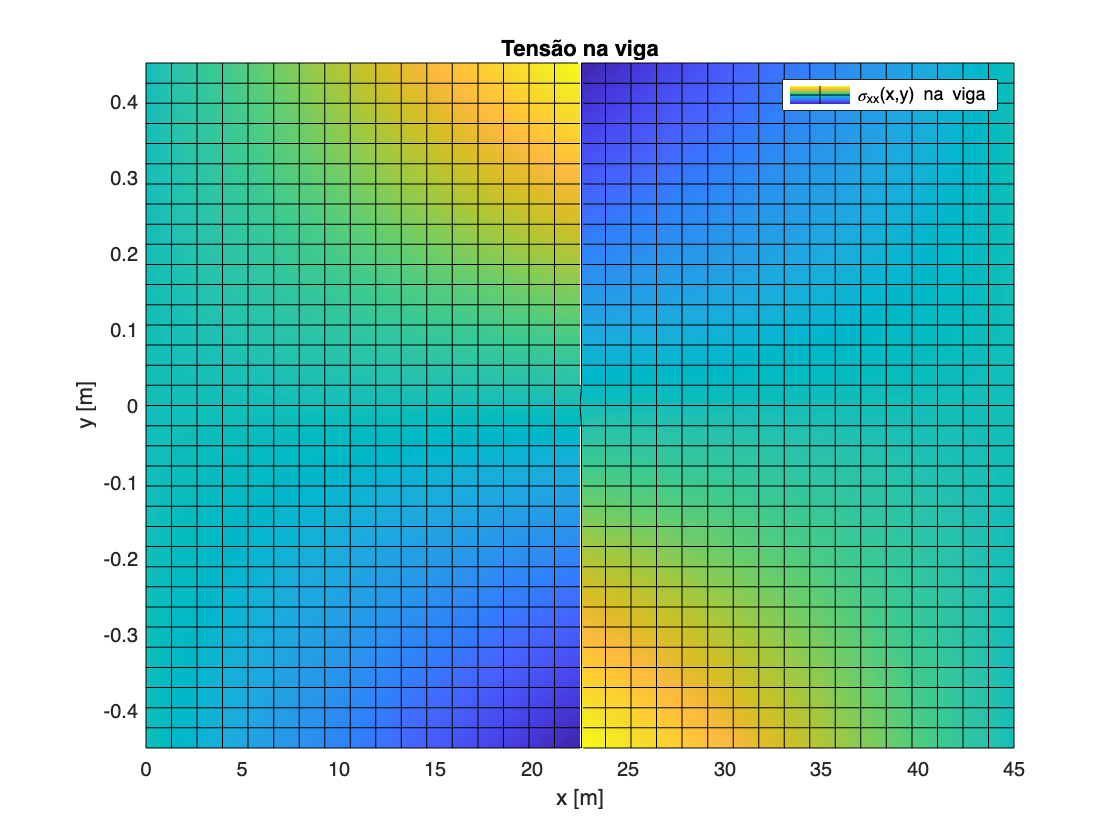

view(2)
title('Tensão na viga');
xlabel('x [m]');
ylabel('y [m]');
legend('\sigma_{xx}(x,y) na viga');

### Discussão

Os gráficos foram criados usando a função fplot para quando temos uma equação com uma incógnita que será variada em um intervalo específico, no caso para $M_z(x) $ e $V_y(x)$. Foi usada também a função plot para gerar o gráfico de uma equação que tenho todos os valores dela em um determinado intervalo, ou para colocar no gráfico os pontos de interesse.

Além disso, a função fsurf fez com que fosse possível gerar um gráfico no qual se faz a variação de duas variáveis em uma equação.

Usando a função fplot, ela pega uma equação com uma incógnita e varia essa incógnita em um dado intervalo. Ou seja, a prória função faz a discretização das variáveis. Para os outros gráficos, usando plot, a discretização foi feita usando o mesmo intervalo dado no enunciado, usando um valor bem pequeno de variação para que seja gerado um gráfico fiel ao esperado.

Por fim, temos que as unidades dos resultados são:


$$M_z(x) \rightarrow [N.m],  \space com \space x \rightarrow [m]\\
V_y(x) \rightarrow [m] , \space com \space x \rightarrow [m]\\
\sigma_{xx}(x,y) \rightarrow [\frac{N}{m^2}] , \space com \space x \rightarrow [m];y \rightarrow [m]$$


Mudando as unidades de medida da entrada, teriamos que a saída seria diferente, uma vez que precisamos das unidades corretas para gerar essa saída.

## Parte 2 - Deflexão em função de uma carga P

Usando a fórmula da deflexão da viga, definindo um valor fixo para x com sendo na extremidade livre, ou seja $x = L$, e variando o valor de P, conseguimos gerar o seguinte gráfico:

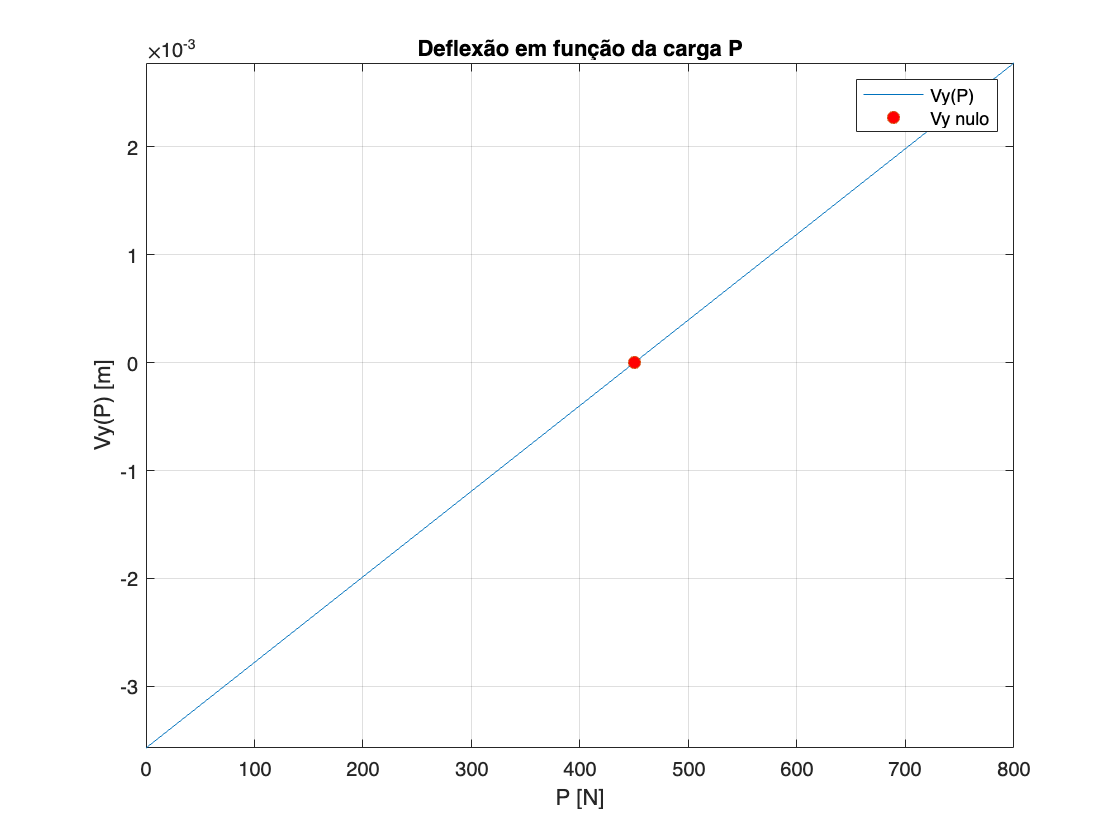

x1 = L;
Vy5 = @(P6) ((P6*L-M0)*x1^2/2 - P6/6*x1^3 + M0/2*sing(x1,L/2,2))/(E*Izz);

figure
fplot(Vy5, [0 2*M0/L])
hold on;
ylabel('Vy(P) [m]');
xlabel('P [N]');
%a deflexao da viga será nula no seguinte ponto:
deflexao_nula = fzero(Vy5, 0.01);
plot(deflexao_nula, 0,'o','MarkerFaceColor','r')
title('Deflexão em função da carga P')
grid on;
legend('Vy(P)', 'Vy nulo')
hold off;

Com isso, temos que $V_y(P) = 0$ para $P = 450 N$. Ou seja, para $P <450$ a deflexão na extremidade da viga será negativa, e para $P > 450$ será positiva.

### Discussão

A função usada para encontrar a raiz da equação, como visto em classe, é a função fzero, que indica qual é o ponto do gráfico em que o eixo P é cruzado. Logo, ao defini a função, temos que o resultado já será a raiz da equação de deflexão.

Ademais, usando a função fzero com a equação de $V_y(P)$ e o valor 0,01, ou seja, $fzero(V_y(P), 0.01)$ chegamos em um valor condizendo com o gráfico, no qual o ponto de $V_y$ nulo cruza o eixo P. Como pode-se observar no gráfico mostrado a cima.

## Parte 3 - Deflexão máxima

Sendo P obtido no item anterior, $P = 450N$, e voltando a variar o valor de x, podemos obter o seguinte gráfico:

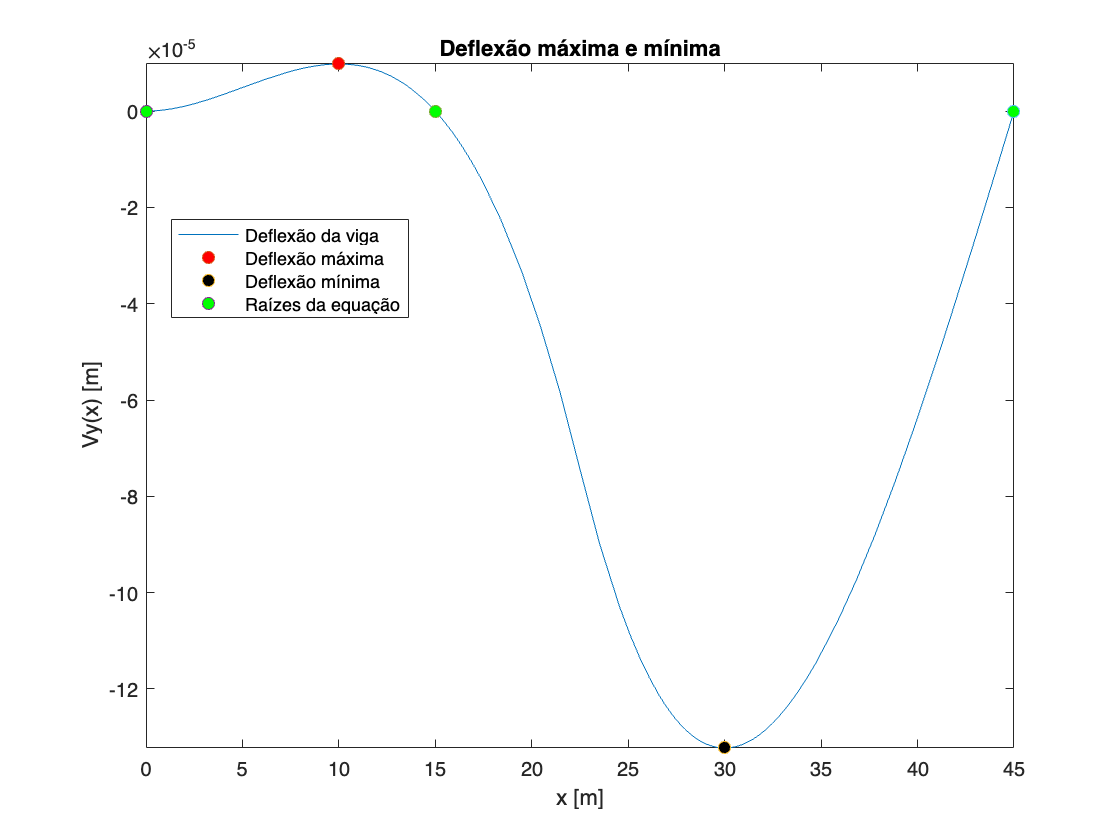

P7 = deflexao_nula;
Vy6 = @(x8) ((P7*L-M0).*x8.^2/2 - P7/6.*x8.^3 + M0/2*sing(x8,L/2,2))/(E*Izz);

fplot(Vy6, [0 L])
hold on;
title('Deflexão máxima e mínima')
xlabel('x [m]');
ylabel('Vy(x) [m]');
xmax = fminbnd(@(x) -Vy6(x),0,L);
Vy6max = Vy6(xmax);
xmin = fminbnd(Vy6,0,L);
Vy6min = Vy6(xmin);
plot(xmax,Vy6max,'o','MarkerFaceColor','r');
plot(xmin,Vy6min,'o','MarkerFaceColor','black');
plot(0,0,'o','MarkerFaceColor','g');
plot(15,0,'o','MarkerFaceColor','g');
plot(45,0,'o','MarkerFaceColor','g');
legend('Deflexão da viga', 'Deflexão máxima','Deflexão mínima','Raízes da equação','Location','best');
hold off;

O ponto onde a deflexão é máxima é em $x = 10m$, no qual $V_y(10) = 9,7982.10^{-6} m$. Além disso, a deflexão é mínima em $x = 30m$, no qual $V_y(30) = -1,3228.10^{-4}m$. Ambos os valores foram encontrados usando a função fminbnd e a função em questão da deflexão.

Ademais, a equação apresenta três pontos nos quais a deflexão é zero, esses pontos são: $x =0m, \space x=15 m\space e \space x =45m$. Valores que foram encontrados com base no gráfico e as seguintes linhas de código:

raiz1 = fzero(Vy1,0)

raiz1 = 0

raiz2 = fzero(Vy1,15)

Exiting fzero: aborting search for an interval containing a sign change
    because NaN or Inf function value encountered during search.
(Function value at -7.60195e+102 is NaN.)
Check function or try again with a different starting value.


raiz2 = NaN

raiz3 = fzero(Vy1,45)

Exiting fzero: aborting search for an interval containing a sign change
    because NaN or Inf function value encountered during search.
(Function value at -5.70146e+102 is NaN.)
Check function or try again with a different starting value.


raiz3 = NaN

Também podemos observar as raízes no gráfico a cima.

### Discussão

A função de otimização utilizada foi a fminbnd, que foi usada para obter os valores máximo e mínimo do gráfico, além da fzero que possibilitou encontrar as raízes da equação.

Os valores obtidos coincidem com um gráfico obtido, como mostrado.

## Parte 4 - Forças de reação

Para a resolução dessa questão foram utilizadas as três equações fornecidas no enunciado, com elas podemos chegar nas matrizes:


$$A = [L \space 0 \space 1 \\
   \space \space \space \frac{3L}{2} \space 0 \space 1 \\
    \space \space \space 1 \space 1 \space 0]$$


e 


$$B = [\frac{w_0.L^2}{2} - M_0 \\
\frac{w_0.(\frac{3L}{2})^2}{2} - M_0 - P(\frac{3L}{3}=L) \\
\frac{w_0(\frac{3L}{2})-P]$$


Com isso, podemos encontrar os resultados esperados, variando o valor de $w_0, \space M_0 \space e \space P$ para zero, conseguimos gerar a tabela:

b3 = (10*d(3) + 2*d(4))*0.01;
h3 = 3*b3;
g = 9.81;
w0 = densidade*b3*h3*g;
P = M0/L;

%Ra Rd Ma
A = [L 0 1
    (3*L/2) 0 1
    1 1 0];

B = [((w0*(L^2)/2)-M0) ((w0*(3*L/2)^2)/2-M0-P*(3*L/2-L)) (w0*(3*L/2)-P)].';

resposta = A\B;

%assumindo w0 = 0
w0_1 = 0;
B1 = [((w0_1*(L^2)/2)-M0) ((w0_1*(3*L/2)^2)/2-M0-P*(3*L/2-L)) (w0_1*(3*L/2)-P)].';
resposta1 = A\B1;

%assumindo w0 = 0 e P = 0
P2 = 0;
B2 = [((w0_1*(L^2)/2)-M0) ((w0_1*(3*L/2)^2)/2-M0-P2*(3*L/2-L)) (w0_1*(3*L/2)-P2)].';
resposta2 = A\B2;


%assumindo w0 = 0 e M0 = 0
M0_1 = 0;
B3 = [((w0_1*(L^2)/2)-M0_1) ((w0_1*(3*L/2)^2)/2-M0_1-P*(3*L/2-L)) (w0_1*(3*L/2)-P)].';
resposta3 = A\B3;


%fazendo a tabela, temos
table1 = table(["Ra" "Rd" "Ma"]',resposta, resposta1, resposta2, resposta3)

table1 = 3×5 table
    Var1     resposta       resposta1     resposta2     resposta3 
    ____    ___________    ___________    _________    ___________

    "Ra"     1.1692e+06           -400          0             -400
    "Rd"     2.3391e+05    -1.6169e-13          0      -5.6843e-14
    "Ma"    -3.1578e+07    -1.0914e-11     -18000            18000


### Discussão

O sistema linear das equações foi evidenciado nas matrizes a cima.

Além disso, foi utilizado a função A\B para que pudesse ser resolvido o sistema de matrizes apresentado. Foi escolhido tal função por conta de ser a ideia para resolver um sistema com duas matrizes.

Os resultados foram armazenados em variáveis diferentes como pode ser visto no código apresentado a cima.

E por fim, foram criadas novas equações para todas os casos em que foram alteradas alguma das variáveis da matriz B.

## Funções utilizadas

As equações abaixo foram utilizadas na parte zero do trabalho. Foram colocadas no fim para que o arquivo pudesse ser gerado o Live Script.

function [L,Izz,M0] = dados(d)
 %A função calcula o comprimento L em metros, a seção transversal em metros e consequentemente Izz.
 %E por fim, o Momento zero em Newton metro.
 
 
%% Comprimento:
%Calculando L, se os ultimos dois digitos do RA forem zeros, L = 5, caso
%contrário, L = 10d5+d6. Isso em metros (m)
if (d(5) + d(6) == 0)
   L = 5;
else
    L = d(5)*10 + d(6);
end


%% Seção transversal:
%Calculando o valor de b e h, em metros (m)
b = (10*d(3) + 2*d(4))*0.01;
h = 3*b;
Izz = (b*h^3)/12;

%% Carregamento:
%Calculando o valor de M0, em Newton vezes metros (N.m)
M0 = (10*d(1) + d(2))*1000;

end



function [d] = converteRA(RA)
%função que converte o RA lido, que é uma string, em um vetor vertical. No
%qual cada linha é um número do RA.
 x = str2num(RA);
 
 ra = x;
 d1 = (ra/100000) - rem(ra,100000)/100000;
 ra = ra - 100000*d1;
 d2 = (ra/10000) - rem(ra,10000)/10000;
 ra = ra - 10000*d2;
 d3 = (ra/1000) - rem(ra,1000)/1000;
 ra = ra - 1000*d3;
 d4 = (ra/100) - rem(ra,100)/100;
 ra = ra - 100*d4;
 d5 = (ra/10) - rem(ra,10)/10;
 d6 = ra - 10*d5;
 
 d = [d1 d2 d3 d4 d5 d6]';
 
end


function y = sing(x,a,n)
%singularity function: y =<x-a>^n
 b = (x>=a);
 y = (x-a).^n .* (b);

end
